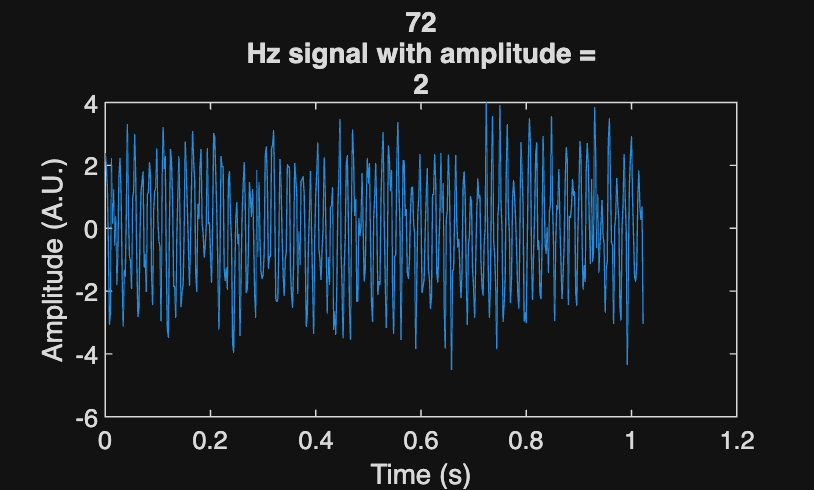

%{
ES115-Control Panel Class-Project
Author: Nivea Williamson
Version: 1.0
Date: 2026-04-27
Purpose:
    Find the frequency of a noisy signal using the Fast Fourier Transform.

Input:
    - Random signal amplitude
    - Random signal frequency
    - Sampling frequency
    - Time vector
    - Noisy signal

Output:
    - Plot of noisy signal in time domain
    - Plot of signal in frequency domain
    - Frequency peak stored as fftFrequency

Engineering Algorithms:
    - Create a noisy signal
    - Use fft to convert the signal from time domain to frequency domain
    - Create a frequency vector
    - Find the largest peak in the FFT
    - Store the frequency of the peak

MATLAB tools/functions:
    - randi
    - randn
    - cos
    - fft
    - abs
    - max
    - plot
    - xlabel and ylabel
    -
-
%} 
% FINDING A SIGNAL THROUGH THE NOISE

clear;
clc;

A = randi([1 5]);                % amplitude between 1 and 5
f = randi([50 79]);              % frequency between 50 and 79 Hz

Fs = 500;                        % sampling frequency in Hz
dt = 1/Fs;                       % sampling period
L = 512;                         % number of points

t = (0:L-1)*dt;                  % time vector

S = A*cos(2*pi*f*t) + randn(size(t));   % signal with noise

figure;
plot(t,S)

title([num2str(f), " Hz signal with amplitude = ", num2str(A)])
xlabel("Time (s)");
ylabel("Amplitude (A.U.)");


Y = fft(S);                      % take FFT of signal

P2 = abs(Y/L)                  % two-sided spectrum

P2 =     0.0420    0.0807    0.0252    0.0704    0.0311    0.0559    0.0501    0.0577    0.0239    0.0479    0.0663    0.0764    0.0282    0.0265    0.0240    0.0075    0.0205    0.0394    0.0145    0.0489    0.0772    0.0417    0.0676    0.0520    0.0238    0.0418    0.0423    0.0390    0.0718    0.0306    0.0341    0.0277    0.0437    0.0563    0.0324    0.0663    0.0402    0.0209    0.0567    0.0743    0.0246    0.0304    0.0444    0.0403    0.0685    0.0214    0.0335    0.0217    0.0483    0.0680


P1 = P2(1:L/2+1)              % one-sided spectrum

P1 =     0.0420    0.0807    0.0252    0.0704    0.0311    0.0559    0.0501    0.0577    0.0239    0.0479    0.0663    0.0764    0.0282    0.0265    0.0240    0.0075    0.0205    0.0394    0.0145    0.0489    0.0772    0.0417    0.0676    0.0520    0.0238    0.0418    0.0423    0.0390    0.0718    0.0306    0.0341    0.0277    0.0437    0.0563    0.0324    0.0663    0.0402    0.0209    0.0567    0.0743    0.0246    0.0304    0.0444    0.0403    0.0685    0.0214    0.0335    0.0217    0.0483    0.0680


P1(2:end-1) = 2*P1(2:end-1)

P1 =     0.0420    0.1615    0.0503    0.1408    0.0622    0.1118    0.1002    0.1154    0.0478    0.0958    0.1326    0.1527    0.0564    0.0530    0.0479    0.0150    0.0411    0.0789    0.0291    0.0979    0.1545    0.0833    0.1352    0.1040    0.0476    0.0837    0.0846    0.0780    0.1435    0.0611    0.0681    0.0555    0.0874    0.1126    0.0648    0.1327    0.0804    0.0419    0.1134    0.1486    0.0492    0.0608    0.0889    0.0806    0.1371    0.0427    0.0671    0.0434    0.0965    0.1359



freq = Fs*(0:(L/2))/L           % frequency vector from 0 to Fs/2

freq =          0    0.9766    1.9531    2.9297    3.9062    4.8828    5.8594    6.8359    7.8125    8.7891    9.7656   10.7422   11.7188   12.6953   13.6719   14.6484   15.6250   16.6016   17.5781   18.5547   19.5312   20.5078   21.4844   22.4609   23.4375   24.4141   25.3906   26.3672   27.3438   28.3203   29.2969   30.2734   31.2500   32.2266   33.2031   34.1797   35.1562   36.1328   37.1094   38.0859   39.0625   40.0391   41.0156   41.9922   42.9688   43.9453   44.9219   45.8984   46.8750   47.8516



[~, idx] = max(P1)             % find index of largest peak

idx = 75


fftFrequency = freq(idx)        % frequency of noisy signal

fftFrequency = 72.2656

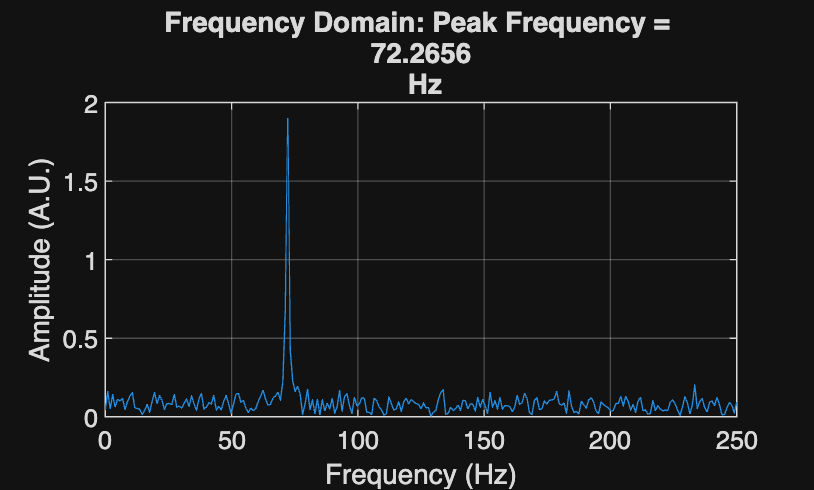


figure;
plot(freq,P1)

title(["Frequency Domain: Peak Frequency = ", num2str(fftFrequency), " Hz"])
xlabel("Frequency (Hz)")
ylabel("Amplitude (A.U.)")

grid on


fprintf("Original signal frequency: %.2f Hz\n", f)

Original signal frequency: 72.00 Hz


fprintf("FFT peak frequency: %.2f Hz\n", fftFrequency)

FFT peak frequency: 72.27 Hz
